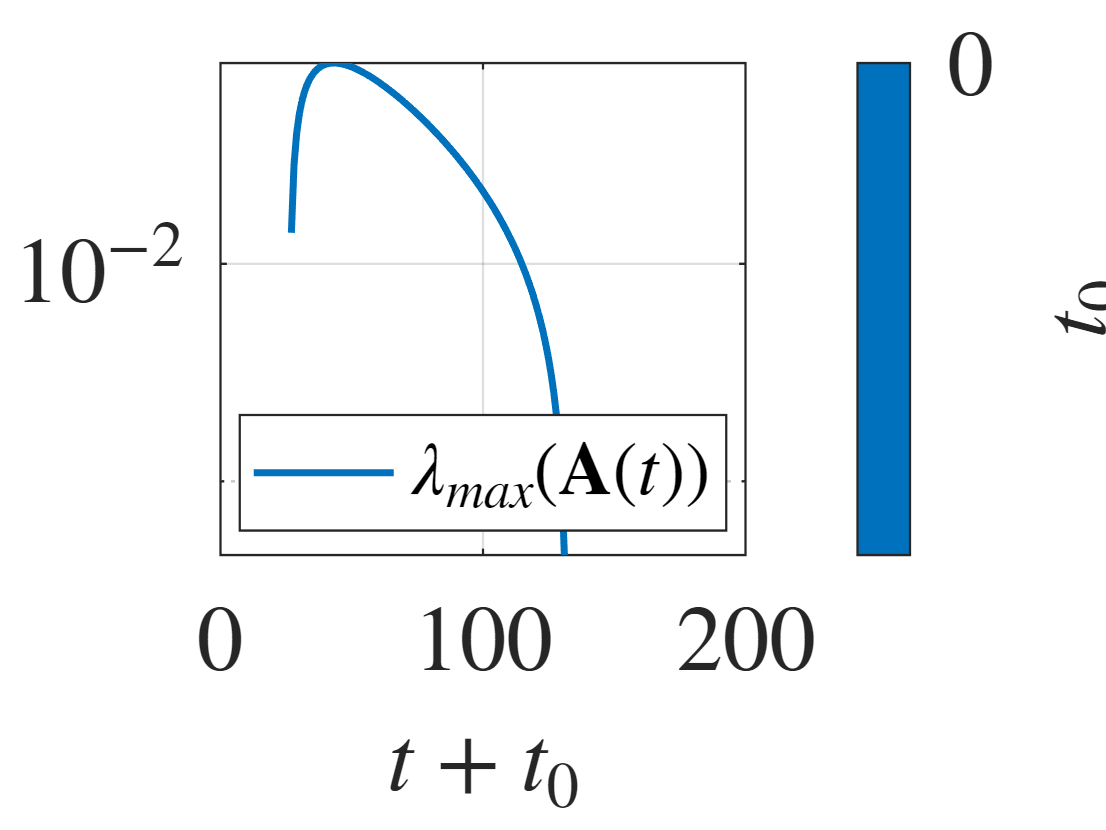

figure;
hold on;
cmap = lines(length(t0)); % Colormap for different t0 values
set(groot, 'defaultTextInterpreter', 'latex');
set(gca, 'TickLabelInterpreter', 'latex', 'FontSize', 20);

for j3 = 1:length(t0)
    if ~isempty(max_eigA{j3})
        % Create time vector: [t0 + dt, t0 + 2*dt, ..., T]
        time_points = t0(j3) + (1:length(max_eigA{j3}))*dt;
        
        % Plot max eigenvalue vs shifted time
        plot(time_points, max_eigA{j3}, ...
                 'Color', cmap(j3,:), ...
                 'LineWidth', 1.5);
    end
end

% Configure colorbar
c = colorbar;
colormap(cmap);
c.Ticks = linspace(0, 1, length(t0));
c.TickLabels = arrayfun(@(x) num2str(x), t0, 'UniformOutput', false);
c.FontSize = 20;
c.Label.String = '$t_0$';
c.Label.Interpreter = 'latex';
c.TickLabelInterpreter = 'latex';
legend({'$\lambda_{max}(\mathbf{A}(t))$'}, 'Location', 'best','Interpreter', 'latex','FontSize',16);

% Axis labels and formatting
xlabel('$t + t_0$', 'FontSize', 20);
% ylabel('', 'FontSize', 20);
grid on;
box on;
xlim([0, T]); % T = 200
set(gca, 'YScale', 'log'); % Logarithmic y-axis

hold off;





% figure;
% hold on;
% cmap = lines(length(t0)); % Colormap for different t0 values
% set(groot, 'defaultTextInterpreter', 'latex');
% set(gca, 'TickLabelInterpreter', 'latex', 'FontSize', 20);
% 
% for j3 = 1:length(t0)
%     if ~isempty(min_eigA{j3})
%         % Create time vector: [t0 + dt, t0 + 2*dt, ..., T]
%         time_points = t0(j3) + (1:length(min_eigA{j3}))*dt;
%         
%         % Plot max eigenvalue vs shifted time
%         semilogy(time_points, min_eigA{j3}, ...
%                  'Color', cmap(j3,:), ...
%                  'LineWidth', 1.5);
%     end
% end
% 
% % Configure colorbar
% c = colorbar;
% colormap(cmap);
% c.Ticks = linspace(0, 1, length(t0));
% c.TickLabels = arrayfun(@(x) num2str(x), t0, 'UniformOutput', false);
% c.FontSize = 20;
% c.Label.String = '$t_0$';
% c.Label.Interpreter = 'latex';
% c.TickLabelInterpreter = 'latex';
% legend({'$\lambda_{min}(\mathbf{A}(t))$'}, 'Location', 'best','Interpreter', 'latex','FontSize',16);
% 
% % Axis labels and formatting
% xlabel('$t + t_0$', 'FontSize', 20);
% % ylabel('', 'FontSize', 20);
% grid on;
% box on;
xlim([0, T]); % T = 200
set(gca, 'YScale', 'log'); % Logarithmic y-axis

hold off;